# Project 0: MATLAB

The goal of this project is to help you get oriented with MATLAB, become aware of common pitfalls, and practice performing operations that will come up in forthcoming MATLAB projects in CS443.

**General instructions:** Write code in each cell beneath the instructional bullet points to compute what's called for. **No loops unless explicitly called for** in the instructions. Toward the end, you will be asked to write your own `.m` files that you will call from here.

## Task 1) Basics: data representation and manipulation

### 1a. Arrays

#### (1) Size of arrays

- Print the size of the 3rd and 5th dimensions of the following array `m`.

m = zeros(1, 2, 3, 4, 5, 1);
size(m,[3,5])

ans =      3     5


#### (2) Singleton dimensions

- Remove the singleton dimensions from m, print out the new dimensions ("shape").

m = zeros(1, 2, 3, 4, 5, 1);
size(squeeze(m))

ans =      2     3     4     5


#### (3) Array concatenation along rows

- Take the following vectors and concatenate them along the row dimension — i.e. there should be 3 rows afterwards. Print the "shape".

a = [1, 2, 3, 4];
b = [1, 2, 3, 4];
c = [1, 2, 3, 4];
size([a;b;c])

ans =      3     4


#### (4) Array concatenation along columns

- Make 3 row vectors: 1) 150 equally space values between 0 and 1 (inclusive); 2) 150 random ints between 10 and 20 (inclusive); 3) 150 gaussian random numbers centered on 10 with standard deviation 5. Concatenate them along the column dimension — i.e. ultimately, there should only be one row.

- Print the "shape".

a = linspace(0,1,150)

a =          0    0.0067    0.0134    0.0201    0.0268    0.0336    0.0403    0.0470    0.0537    0.0604    0.0671    0.0738    0.0805    0.0872    0.0940    0.1007    0.1074    0.1141    0.1208    0.1275    0.1342    0.1409    0.1477    0.1544    0.1611    0.1678    0.1745    0.1812    0.1879    0.1946    0.2013    0.2081    0.2148    0.2215    0.2282    0.2349    0.2416    0.2483    0.2550    0.2617    0.2685    0.2752    0.2819    0.2886    0.2953    0.3020    0.3087    0.3154    0.3221    0.3289


b = randi(11,1,150)+9

b =     19    20    10    17    10    11    11    14    12    13    12    14    14    17    18    12    19    18    19    12    10    16    17    11    11    16    18    18    10    18    19    14    10    12    18    10    14    15    20    12    11    17    11    20    12    16    18    19    15    18


c = normrnd(10,5,1,150)

c =    10.0168   15.4698    8.3646    9.8431    2.4584   11.5113   10.4487   12.6405   11.6910    6.6533   13.3202   23.0508    6.7927   14.6614    7.1112    5.4579    4.3859   12.8768   10.1662   14.3685    9.0499    4.1232    9.0083    9.6312   13.0620    3.9478    0.7844   12.2942    6.1173    7.5461   12.7519   10.0917   10.8246   15.9215   15.3295   10.0180    7.3416    4.0311   11.5788   21.5654   15.2354   11.1248    4.5105    3.8707    7.3499   -8.7109   12.0869   16.2175   10.5529    8.3646


size([a,b,c])

ans =      1   450


#### (5) Math operations

- Compute and print the variance of the following array `x`. You cannot use loops and you cannot use the built-in functions `var`, `std`, and `mean`. Recall, the formula is: 


$$\frac{1}{N-1}\sum_{i=1}^N(x_i - \mu)^2$$


x = 10:50;
mean = sum(x,"all")/size(x,2);
sum((x-mean).^2,"all")/(size(x,2)-1)

ans = 143.5000

### 1b. Indexing

#### (6) Operations along an axis

- Print the minimum values along the 2nd dimension of the following array. No loops.

rng(0);  % Keep me here, I am a random seed.
x = rand(1, 2, 2);
min(x,[],2)

ans = ans(:,:,1) =

    0.8147


ans(:,:,2) =

    0.1270


#### (7) Operations along all axes

- Print the global minimum value in the following array. No loops.

rng(0);  % Keep me here, I am a random seed.
x = rand(10, 9, 8, 7, 6, 5, 4, 3, 2);
min(x,[],"all")

ans = 2.0838e-07

#### (8) Slicing

- Print the second half of the rows and the first quarter of columns — i.e. for this example last 4 rows and first 4 columns. No loops and no hard-coding sizes. *Hint: Pay attention to off-by-one errors!*

- Print the minimum value (one value) in this submatrix.  No loops.

rng(0);  % Keep me here, I am a random seed.
x = rand(8, 16);
y = x(size(x, 1)/2+1:end, 1:size(x, 2)/4)

y =     0.6324    0.9572    0.6557    0.6555
    0.0975    0.4854    0.0357    0.1712
    0.2785    0.8003    0.8491    0.7060
    0.5469    0.1419    0.9340    0.0318


min(y,[],"all")

ans = 0.0318

#### (9) Getting and using an index

- Find the INDEX of the minimum value in the matrix `a`. **Print the value at that index in the matrix **`b`. For example, if a = [1, 0, 2] and b = [2, 3, 4], the desired value is 3. No loops.

rng(0);  % Keep me here, I am a random seed.
a = rand(15, 1);
b = rand(15, 1);
[m,i] = min(a,[],"all","linear")

m = 0.0975

i = 6

b(i)

ans = 0.6557

#### (10) More advanced (but useful) indexing

- Print the values in matrix b that are in the same positions as the minimum values across the 1st dimension of matrix `a` (rows). No loops. *Hint:* the matrices have 15 rows and 3 columns so the min across the 1st dimension returns 3 values so the final result should have 3 values.

rng(0);  % Keep me here, I am a random seed.
a = rand(15, 3);
b = rand(15, 3);
[~, i] = min(a, [], 1, "linear")

c =     0.0975    0.0357    0.0318


i =      6    22    32


b(i)

ans =     0.2760    0.5472    0.1966


#### (11) Element-wise operations

- Take the element-wise maximum between the following two matrices. Print out the sum of the resulting vector. No loops.

rng(0);  % Keep me here, I am a random seed.
a = rand(151, 1);
b = rand(151, 1);
sum(min(a,b),"all")

ans = 48.8431

#### (12) Logical indexing

- Find and print the number of elements in the following array that are larger than 10 but less than 20 (exclusive on both ends of the bounds). No loops.

rng(0);
x = randi(100, [99, 1]);
numel(x(x<20 & x>10))

ans = 10

#### (13) Slicing then applying operations along all axes

- In the following array, sum together all the elements in the 1st dimension, the first 5 elements of the 2nd dimension, and the last 2 elements in the 3rd dimension. No loops. *Hint: Pay attention to off-by-one errors!*

rng(0);
a = rand(2, 10, 20);
sum(a(1,1:5,end-1:end),"all")

ans = 4.7296

#### (14) Binary singleton expansion

- Use binary singleton expansion (bsx) to multiply the following arrays together ELEMENT-WISE and then print the sum (one scalar value output). No loops and you can use implicit operator expansion (i.e. no need to explicitly call `bsxfun`).

a = ones(23, 24, 25);
b = 2*ones(2, 23, 24);
sum(shiftdim(a, -1) .* b, "all")

ans = 55200

## Task 2) Functions

### 2a. True functions

#### (15) Function 1/2

- Write a function in a file called `sumNotI.m`. Your function should take in an array and return an array with the same shape. Every element $i$ of the array should be the sum of all the OTHER elements in the array (across all dimensions) EXCEPT for that element $i$. **Your function should work with arrays of ANY number of dims (not just 1 or 2).** See comment below for example output for `test_1`.

test_1 = [1, 2; 3, 4];
rng(0);
test_2 = randi(10, 2, 1, 2, 1, 2);

disp(sumNotI(test_1))  % [9, 8; 7, 6]

     9     8
     7     6




disp(sumNotI(test_2))


(:,:,1,1,1) =

    39
    38


(:,:,2,1,1) =

    46
    38


(:,:,1,1,2) =

    41
    47


(:,:,2,1,2) =

    45
    42



#### (16) Function 2/2

- Write a function file called `sumAll.m` that sums all the elements of an array passed in that could any number of dimensions.

a = ones(10, 9, 8, 7, 6, 5, 4);
disp(sumAll(a));

val = 604800

      604800



### 2b. Function handles

#### (17) Function handles

- Use a function handle to define a lambda function for a 1D Gaussian with $\mu$ and $\sigma^2$ parameters. Use it to print the value of a gaussian with mean 9 and variance of 2 at x=10. Don't make a wrapper for a built-in function; write it from scratch.

gauss = @(x, mu, sigmasqr) 1/(sqrt(2*pi*sigmasqr)) * exp(-((x - mu).^2)/sigmasqr);
x = 6:12;
gauss(x, 9, 2)

ans =     0.0031    0.0382    0.1711    0.2821    0.1711    0.0382    0.0031


#### (18) Using function handles

- Evaluate your Gaussian on finely separated sample points (equally spaced) and print out the sum multipled by the spacing between any two sample points. The output should make sense ;)

x = 0:.001:10;
sum(gauss(x,1,1)) .* 0.001

ans = 0.6516

## Task 3) Loops and vectorization

#### (19) Subarray assignment

- Loop through the last dimension of `x` and assign to each position the corresponding 2x3 submatrix of `y`. Print the output (might be a little long but that's ok). Only use ONE loop (no nested loops).

rng(0);
x = ones(2, 3, 4);
y = randi(10, [4, 2, 3]);

for i = 1:numel(x)
    x(i) = y(i)
end

x = x(:,:,1) =

     9     1     1
     1     1     1


x(:,:,2) =

     1     1     1
     1     1     1


x(:,:,3) =

     1     1     1
     1     1     1


x(:,:,4) =

     1     1     1
     1     1     1


x = x(:,:,1) =

     9     1     1
    10     1     1


x(:,:,2) =

     1     1     1
     1     1     1


x(:,:,3) =

     1     1     1
     1     1     1


x(:,:,4) =

     1     1     1
     1     1     1


x = x(:,:,1) =

     9     2     1
    10     1     1


x(:,:,2) =

     1     1     1
     1     1     1


x(:,:,3) =

     1     1     1
     1     1     1


x(:,:,4) =

     1     1     1
     1     1     1


x = x(:,:,1) =

     9     2     1
    10    10     1


x(:,:,2) =

     1     1     1
     1     1     1


x(:,:,3) =

     1     1     1
     1     1     1


x(:,:,4) =

     1     1     1
     1     1     1


x = x(:,:,1) =

     9     2     7
    10    10     1


x(:,:,2) =

     1     1     1
     1     1     1


x(:,:,3) =

     1     1     1
     1     1     1


x(:,:,4) =

     1     1     1
     1     1     1


x = x(:,:,1) =

     9     2     7
    10    10     1


x(:,:,2) =

     1     1     1
     1     1     1


x(:,:,3) =

     1     1     1
     1     1     1


x(:,:,4) =

     1     1     1
     1     1     1


x = x(:,:,1) =

     9     2     7
    10    10     1


x(:,:,2) =

     3     1     1
     1     1     1


x(:,:,3) =

     1     1     1
     1     1     1


x(:,:,4) =

     1     1     1
     1     1     1


x = x(:,:,1) =

     9     2     7
    10    10     1


x(:,:,2) =

     3     1     1
     6     1     1


x(:,:,3) =

     1     1     1
     1     1     1


x(:,:,4) =

     1     1     1
     1     1     1


x = x(:,:,1) =

     9     2     7
    10    10     1


x(:,:,2) =

     3    10     1
     6     1     1


x(:,:,3) =

     1     1     1
     1     1     1


x(:,:,4) =

     1     1     1
     1     1     1


x = x(:,:,1) =

     9     2     7
    10    10     1


x(:,:,2) =

     3    10     1
     6    10     1


x(:,:,3) =

     1     1     1
     1     1     1


x(:,:,4) =

     1     1     1
     1     1     1


x = x(:,:,1) =

     9     2     7
    10    10     1


x(:,:,2) =

     3    10     2
     6    10     1


x(:,:,3) =

     1     1     1
     1     1     1


x(:,:,4) =

     1     1     1
     1     1     1


x = x(:,:,1) =

     9     2     7
    10    10     1


x(:,:,2) =

     3    10     2
     6    10    10


x(:,:,3) =

     1     1     1
     1     1     1


x(:,:,4) =

     1     1     1
     1     1     1


x = x(:,:,1) =

     9     2     7
    10    10     1


x(:,:,2) =

     3    10     2
     6    10    10


x(:,:,3) =

    10     1     1
     1     1     1


x(:,:,4) =

     1     1     1
     1     1     1


x = x(:,:,1) =

     9     2     7
    10    10     1


x(:,:,2) =

     3    10     2
     6    10    10


x(:,:,3) =

    10     1     1
     5     1     1


x(:,:,4) =

     1     1     1
     1     1     1


x = x(:,:,1) =

     9     2     7
    10    10     1


x(:,:,2) =

     3    10     2
     6    10    10


x(:,:,3) =

    10     9     1
     5     1     1


x(:,:,4) =

     1     1     1
     1     1     1


x = x(:,:,1) =

     9     2     7
    10    10     1


x(:,:,2) =

     3    10     2
     6    10    10


x(:,:,3) =

    10     9     1
     5     2     1


x(:,:,4) =

     1     1     1
     1     1     1


x = x(:,:,1) =

     9     2     7
    10    10     1


x(:,:,2) =

     3    10     2
     6    10    10


x(:,:,3) =

    10     9     5
     5     2     1


x(:,:,4) =

     1     1     1
     1     1     1


x = x(:,:,1) =

     9     2     7
    10    10     1


x(:,:,2) =

     3    10     2
     6    10    10


x(:,:,3) =

    10     9     5
     5     2    10


x(:,:,4) =

     1     1     1
     1     1     1


x = x(:,:,1) =

     9     2     7
    10    10     1


x(:,:,2) =

     3    10     2
     6    10    10


x(:,:,3) =

    10     9     5
     5     2    10


x(:,:,4) =

     8     1     1
     1     1     1


x = x(:,:,1) =

     9     2     7
    10    10     1


x(:,:,2) =

     3    10     2
     6    10    10


x(:,:,3) =

    10     9     5
     5     2    10


x(:,:,4) =

     8     1     1
    10     1     1


x = x(:,:,1) =

     9     2     7
    10    10     1


x(:,:,2) =

     3    10     2
     6    10    10


x(:,:,3) =

    10     9     5
     5     2    10


x(:,:,4) =

     8     7     1
    10     1     1


x = x(:,:,1) =

     9     2     7
    10    10     1


x(:,:,2) =

     3    10     2
     6    10    10


x(:,:,3) =

    10     9     5
     5     2    10


x(:,:,4) =

     8     7     1
    10     1     1


x = x(:,:,1) =

     9     2     7
    10    10     1


x(:,:,2) =

     3    10     2
     6    10    10


x(:,:,3) =

    10     9     5
     5     2    10


x(:,:,4) =

     8     7     9
    10     1     1


x = x(:,:,1) =

     9     2     7
    10    10     1


x(:,:,2) =

     3    10     2
     6    10    10


x(:,:,3) =

    10     9     5
     5     2    10


x(:,:,4) =

     8     7     9
    10     1    10


#### (20) Loops

- Write a triple nested for loop that multiplies element-by-element `a` to `b` and saves the result in the corresponding position in `c`.

- Print the time required to do all the computations in the order you're most accustomed to in C-like languages (i outer, j middle, k inner). 

- Copy-paste the code into another cell beneath it. Reverse the order in which the loop variables are updated (*in the loop definition only*) — i.e. (k outer, j middle, i inner). Print out the time required now.

- In a 3rd cell, do the computation in a vectorized fashion. Print the time required.

a = ones(50, 100, 150);
b = 2*ones(50, 100, 150);
c = zeros(50, 100, 150);
tic
for i = size(a, 1)
    for j = size(a, 2)
        for k = size(a, 3)
          c(i,j,k) = a(i,j,k) .* b(i,j,k); 
        end
    end
end
toc

Elapsed time is 0.011695 seconds.


a = ones(50, 100, 150);
b = 2*ones(50, 100, 150);
c = zeros(50, 100, 150);
tic
for i = size(a, 3)
    for j = size(a, 2)
        for k = size(a, 1)
          c(k,j,i) = a(k,j,i) .* b(k,j,i); 
        end
    end
end
toc

Elapsed time is 0.011935 seconds.



a = ones(50, 100, 150);
b = 2*ones(50, 100, 150);
c = zeros(50, 100, 150);
tic
c = a .* b;
toc

Elapsed time is 0.014077 seconds.


**Question 1: **Interpret the difference in timing. Why do you observe the pattern of results, particularity in the two for loop cases?

Strangely, the vectorized computation is the slowest on average. This may be due to my low-specced laptop. However, the second loop is clearly faster than the first one. This may be due to how the arrays are stored in memory, and their respective sizes.

#### (21) Array initialization

- Try something you would **never** want to do in Python (and many other languages): Define a `10 x 200,000 `matrix of 0s. Loop through the rows and set all the columns equal to a vector of 1s. But, have your loop variable go from 1 to 50 (in steps of 1). Print out the size and time it takes to run at the end.

tic
x = zeros(10,200000);
for i = 1:50
    x(i,:) = ones(1,200000);
end
toc

Elapsed time is 1.271822 seconds.


**Question 2: **Explain what happened.

It did not throw an error indexing into the 11th row of a 10 row matrix.

- Copy and paste your code in a cell below it. Make a modification to address the point you raised above. Time again.

tic
x = zeros(10,200000);
for i = 1:10
    x(i,:) = ones(1,200000);
end
toc

Elapsed time is 0.094840 seconds.


**Question 3: **What did you find after the modification? Explain what happened.

The code ran a lot faster since it only had to run for a 5th of the rows it ran last time.

## Task 4) Strings and character arrays

#### (22) String comparison

- Check to see if the following string `word` is equal to the string `train`. If it is, print `It equals train!` If it is not `train` and is equal to `test` print `It equals test!` If it is not equal to any of these strings, print `none of the above...`. In all cases, you should do a case-insensitive match.

word = 'tRaInInG';
if strcmpi(word, 'train')
    disp("It equals train");
elseif strcmpi(word, 'test')
    disp("It equals test");
else
    disp("none of the above...");
end

none of the above...


- Copy and paste your code from above in the cell below. Now rewrite your conditions to check if the word BEGINS WITH `train `or `test `(do this case insensitive).

word = 'tRaInInG';
if startsWith(word,"train", 'IgnoreCase',true)
    disp("It equals train");
elseif startsWith(word,"test", 'IgnoreCase',true)
    disp("It equals test");
else
    disp("none of the above");
end

It equals train


#### (23) String representation

**Question 4:** Print the array below. What happened and why?

a = ['red', 'yellow', 'blue', 'green', 'pink', 'orange'];
disp(a)

redyellowbluegreenpinkorange


- Copy-paste the code from the above cell to the cell below, fix the problem to get the intended result. 

- Index into your new collection and create a new variable that contains the subset of colors: 'red', 'green', 'blue' (in that order). Print this new variable to show the correct contents and ordering.

a = ["red", "yellow", "blue", "green", "pink", "orange"];
disp(a)

    "red"    "yellow"    "blue"    "green"    "pink"    "orange"



b = [a(1),a(4),a(3)]

b = 1×3 string array
    "red"    "green"    "blue"


## Task 5) Plotting

#### (24) Working with images

- Load in `star_people.jpg`, convert to grayscale, convert from UINT8 to double, normalize the values so that the absolute largest value could be 1 (i.e. do it so that the normalized image need not contain a 1). Plot it right-side-up.

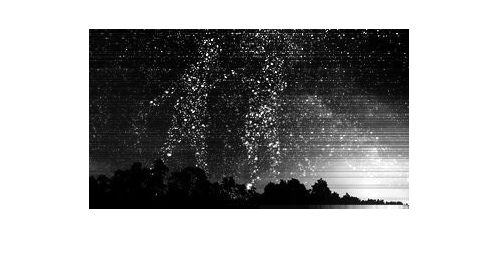

colorImage = imread('star_people.jpg');
greyImage = rgb2gray(colorImage);
greyImage = double(greyImage);
normImage = greyImage ./ max(greyImage);
rotateimg= imrotate(normImage, 270);
imshow(rotateimg)

#### (25) Variable number of function arguments

- Convert your gaussian lambda function into an actual function (in a new file) called `gaussian_vec`. Have it take 2 parameters: the sample points `x` and `varargin`. Give the Gaussian parameters default values. Implement support for  `varargin` to override these defaults. Create a few plots in the cell below demonstrating your use of `varargin` to control the shape/location of the Gaussian.

x = 0:100

x =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


gaussian_vec(x)

ans =     0.3989    0.1468    0.0073    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


gaussian_vec(x,10,5)

ans =     0.0000    0.0000    0.0000    0.0000    0.0001    0.0012    0.0073    0.0295    0.0802    0.1461    0.1784    0.1461    0.0802    0.0295    0.0073    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


#### (26) Basic plotting

- Make ONE plot with 4 Gaussians in it with means of 0 and random variances. **Be sure to add:** 1) a title, 2) x and y axis labels (can just be 'x' and 'y'), 3) a legend, 4) manual curve color selections, 5) manual x and y axis limits that look good.

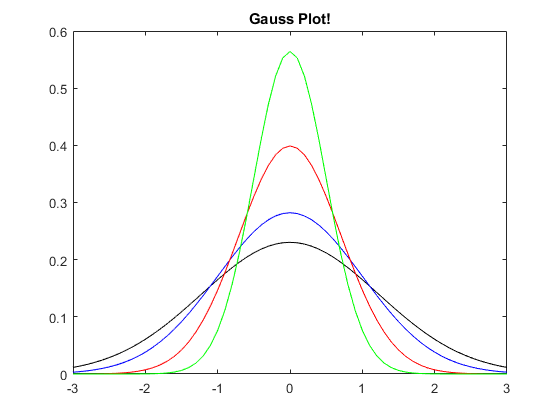

rng(0);
x = -5:0.1:5;
plot(x, gauss(x, 0, 3),'black');
hold on;
plot(x, gauss(x, 0, 2),'blue');
plot(x, gauss(x, 0, 1),'red');
plot(x, gauss(x, 0, 0.5),'green');
title('Gauss Plot!');
xlim([-3,3]);
hold off;

#### (26) Animated plots

- Use your Gaussian function to create a "nice looking" Gaussian vector (*i.e. points when plotted show a nice smooth bell curve*).

- Normalize the Gaussian so that its max value is 1.

- In each iteration of a loop, shift the all the values uniformly over to the left by one position. Values should wrap around. Example: [1, 2, 1] shifted right: [2, 1, 1]

- On each iteration of the loop, plot the updated vector, pausing to make sure that the animation looks smooth. You should see a rigidly moving Gaussian (*soliton wave for you physicists*).

- Feel free to get fancy for fun: have your Gaussian grow/shrink, have the peak rebound off the edges, etc. *No extension points unless you demonstrate a deeper dive into MATLAB's plotting capabilities and customization* (see Extensions section). *In other words, I want you to learn something new!*

x = -5:0.1:5;
GaussVec = gaussian_vec(x, 0, .5);
NormGauss= GaussVec / max(GaussVec,[], "all");
Shifted = NormGauss

Shifted =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0007    0.0015    0.0031    0.0060    0.0111    0.0198    0.0340    0.0561    0.0889    0.1353    0.1979    0.2780    0.3753    0.4868    0.6065    0.7261    0.8353    0.9231    0.9802


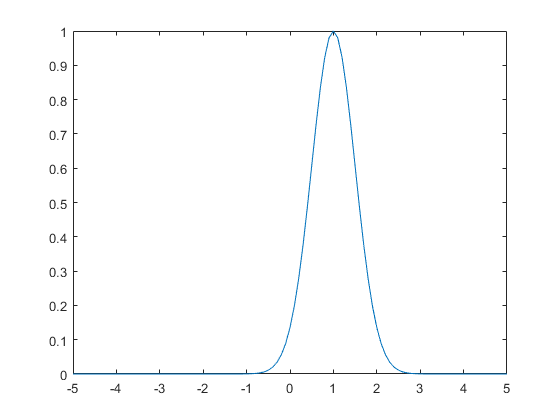

for i = 1:10
    Shifted= circshift(Shifted, 1);
    plot(x, Shifted)
    drawnow
end

#### (27) Outer product

- Use matrix multiplication to convert the 1x10 vector to a symmetric (along main diagonal) 10x10 matrix.

a = 1:10;
b = a' .* a

b =      1     2     3     4     5     6     7     8     9    10
     2     4     6     8    10    12    14    16    18    20
     3     6     9    12    15    18    21    24    27    30
     4     8    12    16    20    24    28    32    36    40
     5    10    15    20    25    30    35    40    45    50
     6    12    18    24    30    36    42    48    54    60
     7    14    21    28    35    42    49    56    63    70
     8    16    24    32    40    48    56    64    72    80
     9    18    27    36    45    54    63    72    81    90
    10    20    30    40    50    60    70    80    90   100


#### (28) Heatmap, array rotation

- Plot heatmaps of rotated versions of the 10x10 matrix in a 2x2 grid of plots (0 deg, 90 deg, 180 deg, and 270 deg).

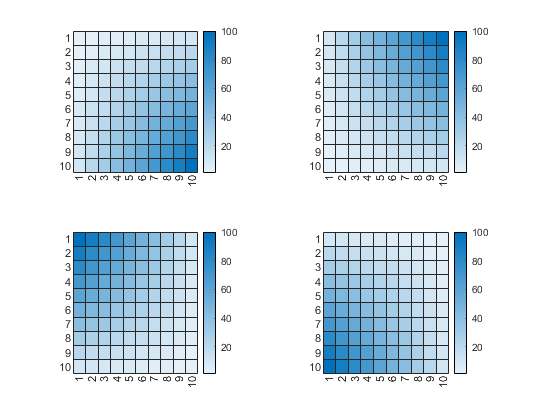

tiledlayout(2,2);
nexttile;
heatmap(b);
b = rot90(b);
nexttile;
heatmap(b);
b = rot90(b);
nexttile;
heatmap(b);
b = rot90(b);
nexttile;
heatmap(b);

## Extensions

Learn and explore another aspect of MATLAB that we did not talk about in class or practice in this project. Check the rubric to keep in mind how extensions on this project will be graded.